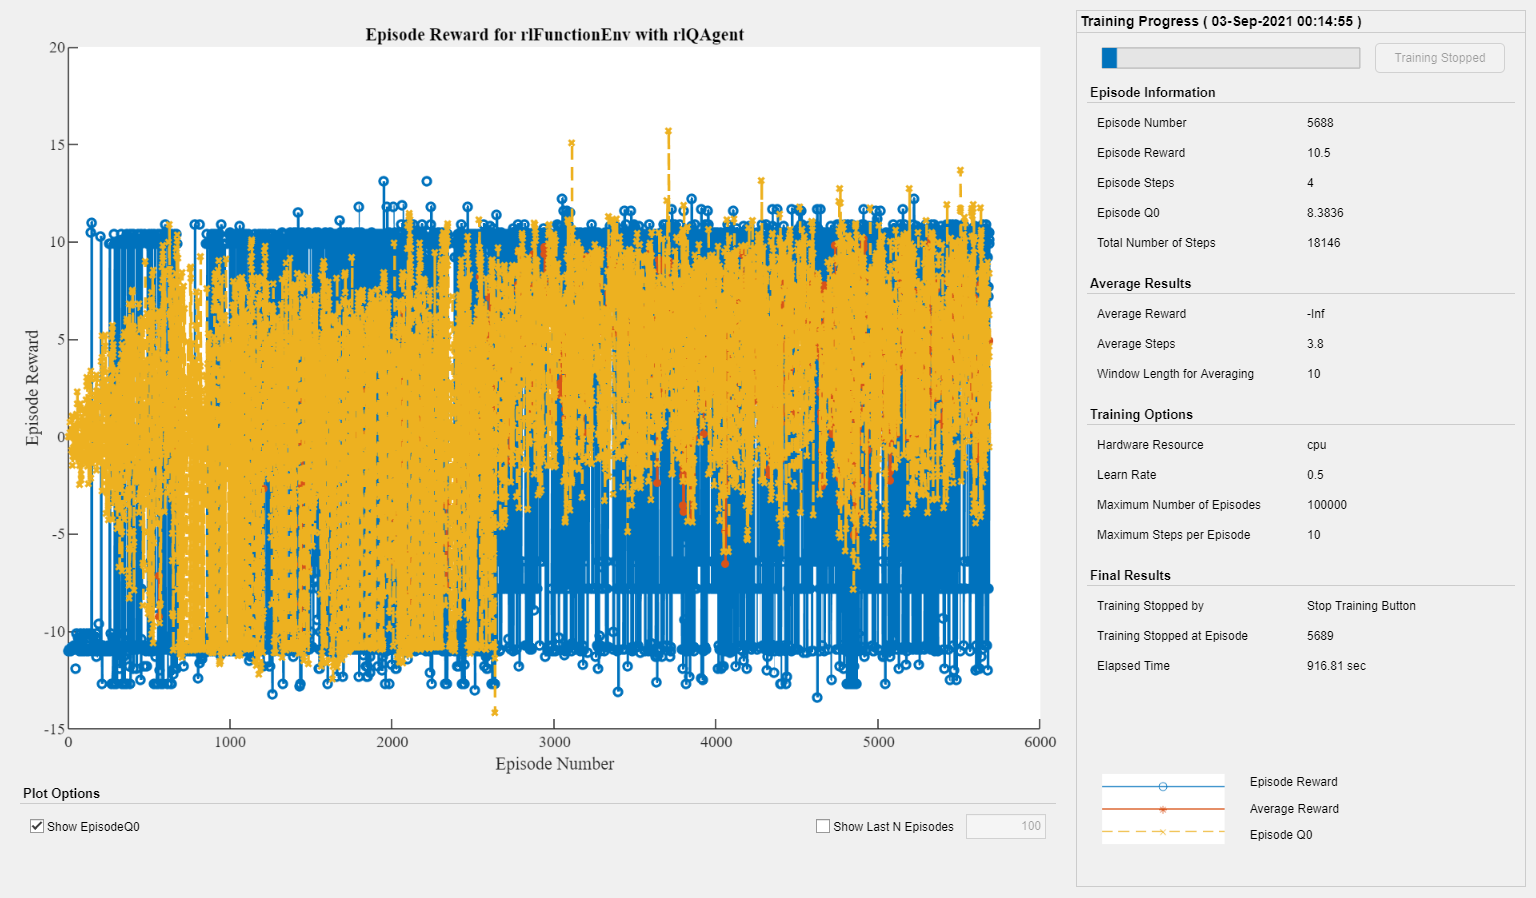

%	Initialise script
Proj = currentProject;
cd(fullfile(Proj.RootFolder, "TicTacToe"));

% %	Create TicTacToe object
% TTT = TicTacToe;

%	Create environment
NumObs = 3^9;		%	Number of observation states (Pl 1, Pl 2 or empty in each grid position)
NumAct = 9;			%	Number of actions (3x3 grid)

OI = rlFiniteSetSpec(1:NumObs);		%	Observation Info
OI.Name = "Tic-Tac-Toe Observation States";

AI = rlFiniteSetSpec(1:NumAct);		%	Action Info
OI.Name = "Tic-Tac-Toe Actions";

env = rlFunctionEnv(OI, AI, @Step, @Reset);
%	Create QTable
qTable = rlTable(OI, AI);
qRepresentation = rlQValueRepresentation(qTable, OI, AI);
qRepresentation.Options.LearnRate = .5;

%	Create Agent Options
agentOpts = rlQAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = .05;
agentOpts.EpsilonGreedyExploration.EpsilonDecay = 1e-3;
agentOpts.EpsilonGreedyExploration.EpsilonMin = 1e-3;
qAgent = rlQAgent(qRepresentation, agentOpts);

%	Set training options
trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 10;
trainOpts.MaxEpisodes= 1e5;
trainOpts.StopTrainingCriteria = "EpisodeCount";
trainOpts.StopTrainingValue = trainOpts.MaxEpisodes;
trainOpts.ScoreAveragingWindowLength = 10;

%	Train the agent
rng(0);
trainingStats = train(qAgent, env, trainOpts);

function [InitState, Data] = Reset()
Data = struct( ...
	"Obj", TicTacToe, ...
	"Player", randi(2), ...
	"Centre", logical(randi(2)-1));
if Data.Player==2
	Data.Obj = Data.Obj.Choose(Data.Centre);
end
InitState = Data.Obj.GetState;
end

%	Step by applying the action to the game board
function [State, Reward, IsDone, Data] = Step(Action, Data)
Rewards = struct( ...
	"Step", -1, ...
	"Win", 10, ...
	"Draw", -5, ...
	"Lose", -10, ...
	"Illegal", -inf);

%	If currentplayer not changed, then return illegal move
if Data.Obj.Grid(Action)
	Result = nan;
else
	%	Attempt to insert counter in grid index Action
	[Row, Col] = ind2sub([3 3], Action);
	Data.Obj = Data.Obj.Insert(Row, Col);
	Result = Data.Obj.CheckWinner;
	if abs(Result)~=1
		Data.Obj = Data.Obj.Choose(Data.Centre);
		Result = Data.Obj.CheckWinner;
	end
end

switch Result
	case Data.Player
		Reward = Rewards.Win;
	case 3-Data.Player
		Reward = Rewards.Lose;
	case -1
		Reward = Rewards.Draw;
	case 0
		Reward = sum(Data.Obj.CalculateScores.^3) * (3-2*Data.Player)/10;
% 		Reward = Rewards.Step;
	otherwise
		Reward = Rewards.Illegal;
end
if ~isfinite(Result) || logical(Result)
	IsDone = true;
else
	IsDone = false;
end

State = Data.Obj.GetState;
end
